clear all;

global  CL_max_Re CL_max_Rec freestream_velocity

wing_name = 'TestWing';

aspect_ratio = 10;
taper_ratio = 0.7;
geo_twist_angle = 4; % degrees
sweep_angle = 15; % degrees
dihedral_angle = 3; % degrees
panel_number = 20;
elliptical_planform = false;
root_chord = 1.0;
flap_percent = 0;
flap_angle = 0;

dihedral_twist_correction = true;
wake_alignment = WakeAlignment.Freestream;
compressibility_correction = false;
non_linear_correction = true;

freestream_velocity = 1;
mach = 0.8;

if compressibility_correction == false
    mach = 0.0;
end

aoa_init = 15;
aoa_final = 20;
aoa_step = 0.5;

aoa_vector = aoa_init:aoa_step:aoa_final;

mean_chord_reynolds = 3e6;

plot_geometry = true;
plot_lift = false;
plot_drag = false;
plot_wake = false;

export_geometry = true;
export_lift = false;
export_drag = false;
export_wake = false;

% Airfoil Selection
use_af_data_1 = false;
use_af_data_2 = false;

airfoil_database_path = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\Airfoil Database.xlsx";

airfoil_1 = 'NACA_23012';
airfoil_2 = 'NACA_0012';

airfoil_path_1 = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\NACA_4418_Kutta_Lift_Model.xlsx"; % Use if getting value from Regression Model
airfoil_path_2 = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\NACA_23012_Kutta_Lift_Model.xlsx"; % Keep same as first path for no airfoil twist

if use_af_data_1

   [aoa_root_0, root_airfoil] = aoa_zero_database(airfoil_1, airfoil_database_path);

else

   [aoa_root_0, root_airfoil] = aoa_zero_regression(airfoil_path_1);

end


if use_af_data_2

    [aoa_tip_0, tip_airfoil] = aoa_zero_database(airfoil_2, airfoil_database_path);
   

else

    [aoa_tip_0, tip_airfoil] = aoa_zero_regression(airfoil_path_2);

end

airfoil_name = root_airfoil;


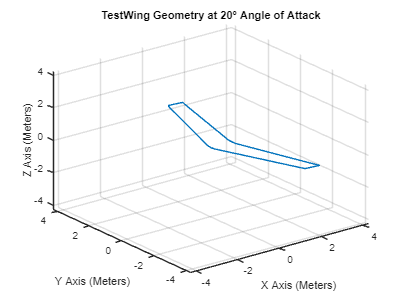

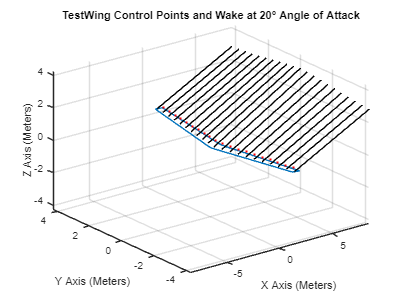

% Wing Geometry Extrapolation

if elliptical_planform  

    tip_chord = 0;


else

    
    tip_chord = taper_ratio * root_chord;

end

wing_span = cosd(dihedral_angle) * aspect_ratio * root_chord * (1 + taper_ratio)/2;

wing_reference_area = (1+taper_ratio) * root_chord * wing_span/2;

for i = 1:size(aoa_vector,2)

    [x_vortex_1, y_vortex_1, z_vortex_1,x_vortex_2, y_vortex_2, z_vortex_2, x_control{i}, y_control{i}, z_control{i}, chord, twist, aoa_0_dist] = generate_wing_geometry(panel_number, wing_span, root_chord, tip_chord, sweep_angle, geo_twist_angle, dihedral_angle, elliptical_planform, aoa_tip_0, aoa_root_0, aoa_vector(i), flap_percent, flap_angle, wake_alignment);

end


aoa_index = 20;
wake_length = 10;

array_index = (aoa_index - aoa_init) / aoa_step + 1;

if plot_geometry
   
      plot_wing_geometry(panel_number, wing_span, root_chord, tip_chord, geo_twist_angle, twist, chord, x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, x_control{array_index}, y_control{array_index}, z_control{array_index}, aoa_index, aoa_0_dist, wake_alignment, wake_length, wing_name, export_geometry);
    
end

wake_plot_title = append([wing_name,' Control Points and Wake at ',  num2str(aoa_index) , '° Angle of Attack']);
       